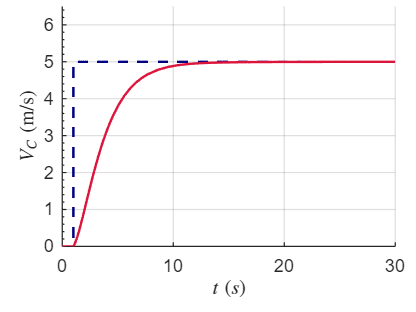

clear
clc


% 0 Controller value

Kp_1 = 97;

Kp_2 = -51.2;

Ki_2 = -0.055;

Kp_3 = -0.033;

Ki_3 = -0.0003;

Kp_4 = -0.00045;

Ki_4 = -0.0022;

% 1 Run model
open('Vertical_Velocity_Hold.slx')
out = sim('Vertical_Velocity_Hold.slx');

% 2 Extract time and signal data
t = out.w.Time;
w = out.w.Data;
step = out.step.Data;

% 3 Compute step response characteristics

% Plot for verification
[ha, pos] = tight_subplot(1,1, ...   % Nh, Nw
                          [0.08 0.08], ...
                          [0.21 0.02], ...    % marg_h [bottom top]
                          [0.15 0.05]);       % marg_w [left  right]

ax = ha(1);            % handle to the only axes
axes(ax);              % activate it

plot(t, -step, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5);
hold on
plot(t, -w, 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5);
hold off

set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';

xlim([0 30]);
ylim([0 6.5]);

xlabel('$t \; (s)$', 'Interpreter', 'latex');
ylabel('$V_{C} \; (\mathrm{m/s})$', 'Interpreter', 'latex');


grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

% Set figure size
set(gcf, 'Position', [0 0 400 300]);


% Compute step response characteristics
info = stepinfo(w, t);
disp('Step Response Characteristics:');

Step Response Characteristics:


disp(info);

         RiseTime: 5.3159
    TransientTime: 10.2557
     SettlingTime: 10.2557
      SettlingMin: -4.9991
      SettlingMax: -4.5629
        Overshoot: 0
       Undershoot: 3.0841e-06
             Peak: 4.9991
         PeakTime: 100

